% Measurement curve calculation

rh = [0,5,10,15,20]

rh =      0     5    10    15    20


c = [161.6,163.6,165.4,167.2,169]

c =   161.6000  163.6000  165.4000  167.2000  169.0000



p_c = polyfit(c,rh,1)

p_c =     2.7161 -439.1356



x = -439.1356 + 2.7161.*c

x =    -0.2138    5.2184   10.1073   14.9963   19.8853


y = [91,100,117,130,145]

y =     91   100   117   130   145


p = polyfit(x,y,1)

p =     2.7557   89.0470


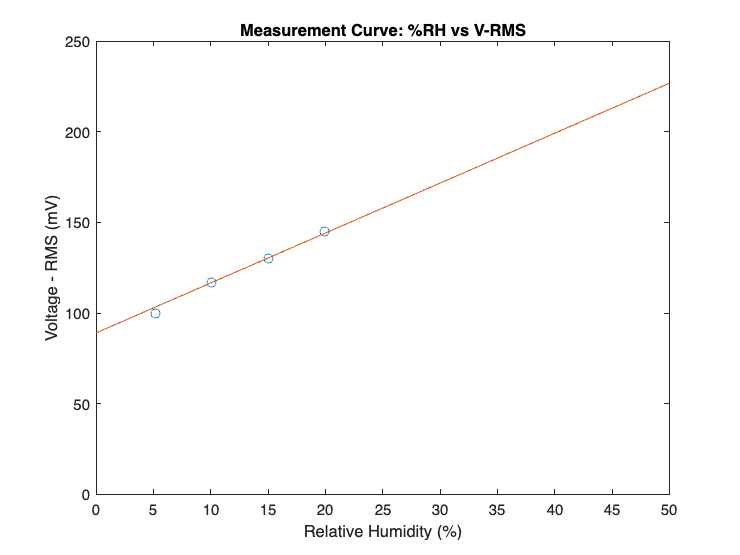

% Plot measurement curve (%RH vs V-RMS)
x1 = linspace(0,200);
y1 = polyval(p,x1);
figure
plot(x,y,'o')
xlim([0 50])
ylim([0 250])
hold on
plot(x1,y1)
hold off
xlabel('Relative Humidity (%)')
ylabel('Voltage - RMS (mV)')
title('Measurement Curve: %RH vs V-RMS')

% Plot measurement curve (C vs %RH)
c = [161.6,163.6,165.4,167.2,169]

c =   161.6000  163.6000  165.4000  167.2000  169.0000


rh = [0,5,10,15,20]

rh =      0     5    10    15    20



p_c = polyfit(c,rh,1)

p_c =     2.7161 -439.1356


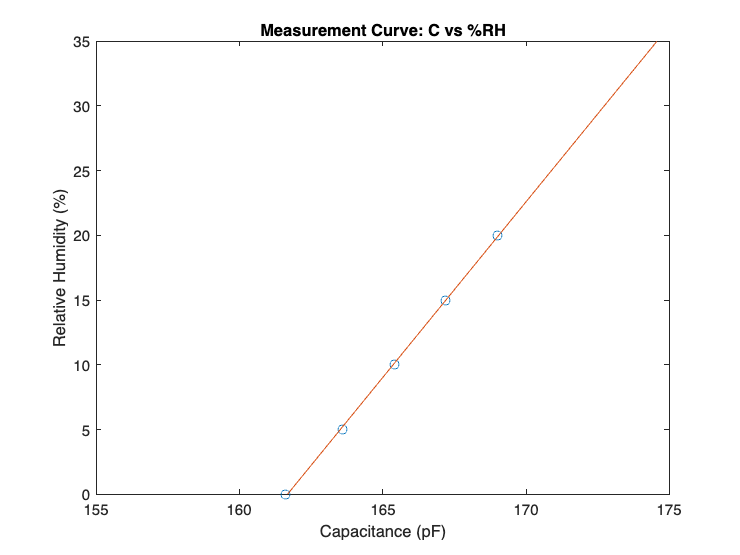


x1 = linspace(0,200);
y1 = polyval(p_c,x1);
figure
plot(c,rh,'o')
xlim([155 175])
ylim([0 35])
hold on
plot(x1,y1)
hold off
xlabel('Capacitance (pF)')
ylabel('Relative Humidity (%)')
title('Measurement Curve: C vs %RH')